clear all
close all
clc

rng(1);

load('Benchmark_EEG_small')


Preprocessing Data

partici = 2    %Choose participant

partici = 2

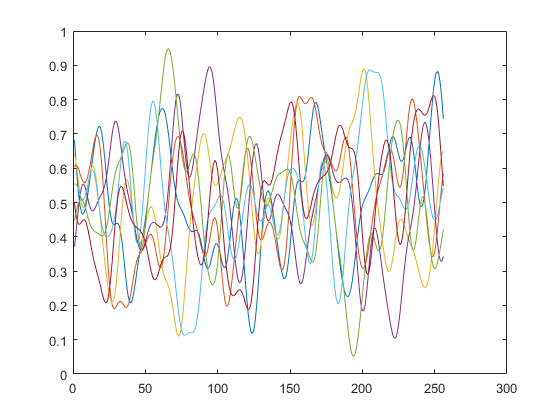


input = squeeze(data.u(partici,:,:))' /6+0.5 ;
output = squeeze(data.y(partici,:,:))'/8+0.5 ;

plot(input)

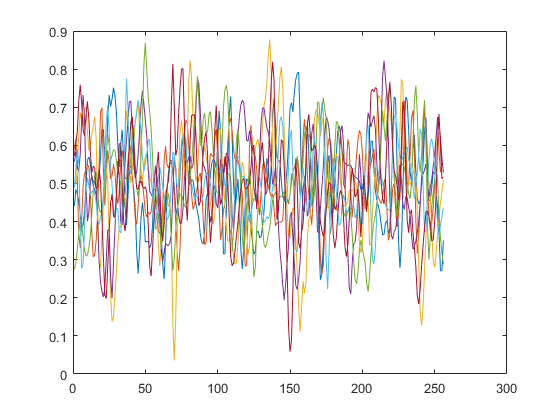

plot(output)


% histogram(input);
% histogram(output);


Choose lags

%angle
inlags=[10 9 8 6 5 4];
for l = 1:length(inlags)
u(:,l) = (reshape(input(end-inlags(l)-241:end-inlags(l)-1,:), [],1));
end

%angular velocity
vlags=[4 5 6];
for l = 1:length(vlags)
v(:,l) = (reshape(input(end-vlags(l)-241:end-vlags(l)-1,:), [],1) - reshape(input(end-vlags(l)-240:end-vlags(l),:), [],1))/0.2+0.5;
end

%output
outlags=[0 1 2 3 4 5];
for l = 1:length(outlags)
y(:,l) = reshape(output(end-outlags(l)-240:end-outlags(l),:), [],1);
end


Split test and training set

for period = 1:7;
testind = (241*(period-1)+1):241*period;

trainind = setdiff([1:size(u,1)],testind);

featurez = [y(trainind,2:end)  v(trainind,:) u(trainind,:)];
zeta = y(trainind,1);

tfeaturez = [y(testind,2:end)  v(testind,:) u(testind,:)];
yt = y(testind,1);



% histogram(featurez(:,1),100)
% 
% inters = 0:0.005:0.995;
% for s = 1:200
% groupz{s} = (featurez(:,1)>= inters(s) & featurez(:,1)< inters(s)+0.005);
% end
% 
% sampled = [];
% sampledzeta= [];
% for s = 1:200
%     if ~isempty(featurez(groupz{s},:))      
% [sam,idx] = datasample(featurez(groupz{s},:),40,1);
% sampled = [sampled ; sam];
% zet = zeta(groupz{s});
% sampledzeta =  [sampledzeta ; zet(idx')];
%     end
% end
% 
% 
% histogram(sampled(:,1),200);
% histogram(sampledzeta(:,1),200);

% 
% featurez = sampled;
% zeta = sampledzeta;


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 2;                 %degree B-spline
m = 2;                  %Number of knot intervals
In = n+m;               %Number of B-splines

un = basisvectors(featurez,n,m);




Initialize tensor train

% Choose TT-ranks
maxrank = 6;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

Compression: 6.1989e-06


Compression: 6.1989e-06


Compression: 6.1989e-06


Compression: 6.1989e-06


Compression: 6.1989e-06


Compression: 6.1989e-06


Compression: 6.1989e-06


Optimize TT cores

lambda=1*10^-5 ;
gamma=0 ;
% gamma=;

difforder=2;
MAXITR = 2*d;

rez = [];
% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);

    "iteration:"    "1"    "0.10861"

    "iteration:"    "2"    "0.19965"

    "iteration:"    "3"    "0.26823"

    "iteration:"    "4"    "0.35177"

    "iteration:"    "5"    "0.41235"

    "iteration:"    "6"    "0.55481"

    "iteration:"    "7"    "0.64152"

    "iteration:"    "8"    "0.7342"

    "iteration:"    "9"    "0.8026"

    "iteration:"    "10"    "0.93212"

    "iteration:"    "11"    "1.0276"

    "iteration:"    "12"    "1.0941"

    "iteration:"    "13"    "1.1618"

    "iteration:"    "14"    "1.2304"

    "iteration:"    "15"    "1.3014"

    "iteration:"    "16"    "1.3674"

    "iteration:"    "17"    "1.4423"

    "iteration:"    "18"    "1.5196"

    "iteration:"    "19"    "1.603"

    "iteration:"    "20"    "1.6649"

    "iteration:"    "21"    "1.732"

    "iteration:"    "22"    "1.7968"

    "iteration:"    "23"    "1.8679"

    "iteration:"    "24"    "1.9311"

    "iteration:"    "25"    "2.0037"

    "iteration:"    "26"    "2.1027"

    "iteration:

    "iteration:"    "1"    "0.067915"

    "iteration:"    "2"    "0.15109"

    "iteration:"    "3"    "0.23087"

    "iteration:"    "4"    "0.30386"

    "iteration:"    "5"    "0.36614"

    "iteration:"    "6"    "0.43383"

    "iteration:"    "7"    "0.49671"

    "iteration:"    "8"    "0.56357"

    "iteration:"    "9"    "0.62459"

    "iteration:"    "10"    "0.69978"

    "iteration:"    "11"    "0.7613"

    "iteration:"    "12"    "0.83479"

    "iteration:"    "13"    "0.90194"

    "iteration:"    "14"    "0.97765"

    "iteration:"    "15"    "1.0429"

    "iteration:"    "16"    "1.1231"

    "iteration:"    "17"    "1.1897"

    "iteration:"    "18"    "1.2576"

    "iteration:"    "19"    "1.3187"

    "iteration:"    "20"    "1.3957"

    "iteration:"    "21"    "1.4688"

    "iteration:"    "22"    "1.5453"

    "iteration:"    "23"    "1.6126"

    "iteration:"    "24"    "1.6892"

    "iteration:"    "25"    "1.7531"

    "iteration:"    "26"    "1.8193"

    "it

    "iteration:"    "1"    "0.07755"

    "iteration:"    "2"    "0.1628"

    "iteration:"    "3"    "0.22584"

    "iteration:"    "4"    "0.28995"

    "iteration:"    "5"    "0.35712"

    "iteration:"    "6"    "0.43782"

    "iteration:"    "7"    "0.50909"

    "iteration:"    "8"    "0.58353"

    "iteration:"    "9"    "0.65023"

    "iteration:"    "10"    "0.71921"

    "iteration:"    "11"    "0.7862"

    "iteration:"    "12"    "0.86236"

    "iteration:"    "13"    "0.92985"

    "iteration:"    "14"    "1.0013"

    "iteration:"    "15"    "1.0646"

    "iteration:"    "16"    "1.1316"

    "iteration:"    "17"    "1.2006"

    "iteration:"    "18"    "1.2848"

    "iteration:"    "19"    "1.3673"

    "iteration:"    "20"    "1.4497"

    "iteration:"    "21"    "1.5308"

    "iteration:"    "22"    "1.698"

    "iteration:"    "23"    "1.8265"

    "iteration:"    "24"    "1.8973"

    "iteration:"    "25"    "1.9736"

    "iteration:"    "26"    "2.0698"

    "iterat

    "iteration:"    "1"    "0.07244"

    "iteration:"    "2"    "0.13199"

    "iteration:"    "3"    "0.196"

    "iteration:"    "4"    "0.25873"

    "iteration:"    "5"    "0.32204"

    "iteration:"    "6"    "0.4033"

    "iteration:"    "7"    "0.49573"

    "iteration:"    "8"    "0.57726"

    "iteration:"    "9"    "0.64769"

    "iteration:"    "10"    "0.70986"

    "iteration:"    "11"    "0.77394"

    "iteration:"    "12"    "0.83631"

    "iteration:"    "13"    "0.90277"

    "iteration:"    "14"    "0.96612"

    "iteration:"    "15"    "1.0339"

    "iteration:"    "16"    "1.1061"

    "iteration:"    "17"    "1.1756"

    "iteration:"    "18"    "1.2466"

    "iteration:"    "19"    "1.3106"

    "iteration:"    "20"    "1.3753"

    "iteration:"    "21"    "1.44"

    "iteration:"    "22"    "1.505"

    "iteration:"    "23"    "1.5696"

    "iteration:"    "24"    "1.6374"

    "iteration:"    "25"    "1.7036"

    "iteration:"    "26"    "1.7688"

    "iteratio

    "iteration:"    "1"    "0.070738"

    "iteration:"    "2"    "0.13224"

    "iteration:"    "3"    "0.19486"

    "iteration:"    "4"    "0.25949"

    "iteration:"    "5"    "0.3237"

    "iteration:"    "6"    "0.38842"

    "iteration:"    "7"    "0.45382"

    "iteration:"    "8"    "0.51993"

    "iteration:"    "9"    "0.58784"

    "iteration:"    "10"    "0.65439"

    "iteration:"    "11"    "0.71896"

    "iteration:"    "12"    "0.78506"

    "iteration:"    "13"    "0.84982"

    "iteration:"    "14"    "0.92215"

    "iteration:"    "15"    "0.98861"

    "iteration:"    "16"    "1.0533"

    "iteration:"    "17"    "1.1166"

    "iteration:"    "18"    "1.1869"

    "iteration:"    "19"    "1.2511"

    "iteration:"    "20"    "1.3185"

    "iteration:"    "21"    "1.3829"

    "iteration:"    "22"    "1.4491"

    "iteration:"    "23"    "1.5119"

    "iteration:"    "24"    "1.5767"

    "iteration:"    "25"    "1.6438"

    "iteration:"    "26"    "1.7145"

    "i

    "iteration:"    "1"    "0.068589"

    "iteration:"    "2"    "0.12921"

    "iteration:"    "3"    "0.20995"

    "iteration:"    "4"    "0.28642"

    "iteration:"    "5"    "0.35058"

    "iteration:"    "6"    "0.41652"

    "iteration:"    "7"    "0.47871"

    "iteration:"    "8"    "0.54508"

    "iteration:"    "9"    "0.60908"

    "iteration:"    "10"    "0.67654"

    "iteration:"    "11"    "0.73921"

    "iteration:"    "12"    "0.8082"

    "iteration:"    "13"    "0.87305"

    "iteration:"    "14"    "0.93974"

    "iteration:"    "15"    "1.003"

    "iteration:"    "16"    "1.072"

    "iteration:"    "17"    "1.1363"

    "iteration:"    "18"    "1.2048"

    "iteration:"    "19"    "1.2687"

    "iteration:"    "20"    "1.3368"

    "iteration:"    "21"    "1.4026"

    "iteration:"    "22"    "1.4705"

    "iteration:"    "23"    "1.5342"

    "iteration:"    "24"    "1.6008"

    "iteration:"    "25"    "1.6864"

    "iteration:"    "26"    "1.7865"

    "iter

    "iteration:"    "1"    "0.072887"

    "iteration:"    "2"    "0.13379"

    "iteration:"    "3"    "0.20415"

    "iteration:"    "4"    "0.26952"

    "iteration:"    "5"    "0.33668"

    "iteration:"    "6"    "0.40285"

    "iteration:"    "7"    "0.47255"

    "iteration:"    "8"    "0.53822"

    "iteration:"    "9"    "0.60842"

    "iteration:"    "10"    "0.71418"

    "iteration:"    "11"    "0.77989"

    "iteration:"    "12"    "0.84514"

    "iteration:"    "13"    "0.93124"

    "iteration:"    "14"    "1.0147"

    "iteration:"    "15"    "1.0799"

    "iteration:"    "16"    "1.143"

    "iteration:"    "17"    "1.2082"

    "iteration:"    "18"    "1.2729"

    "iteration:"    "19"    "1.3388"

    "iteration:"    "20"    "1.4027"

    "iteration:"    "21"    "1.4668"

    "iteration:"    "22"    "1.5305"

    "iteration:"    "23"    "1.5949"

    "iteration:"    "24"    "1.6636"

    "iteration:"    "25"    "1.7273"

    "iteration:"    "26"    "1.7919"

    "ite

rez = [rez res1];

% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)
% 
% plot(rez)

Evaluate Test data


% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% plot(zeta)
% plot(yhattrain)
% hold off
% axis([0 256 -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)


yhat = evalspline(TN,tfeaturez,n,m);


erboi = (yhat-yt);
% histogram((erboi)');
VAF1(period) = 1-var(erboi)/var(yt);
% MSE = immse(yhat,yt)
% 
% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 256 -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off

simfeaturez = tfeaturez;

for j = 1:3
y_k = evalspline(TN,simfeaturez,n,m);

for k = 5:-1:2
simfeaturez(k:end,k) = simfeaturez((k-1):end-1,(k-1));
end
simfeaturez(2:end,1) = y_k(1:end-1);

end

ysim = simfeaturez(4:end,1);

% figure
% hold on
% plot(yt(2:end-2),'linewidth',2)
% plot(ysim,'linewidth',2)
% hold off
% axis([0 256 -inf inf])

VAF(period) = 1-var(yt(2:end-2)-ysim)/var(yt);

end

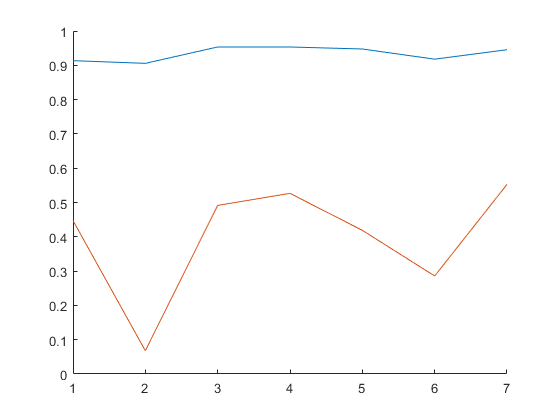

figure 
hold on
plot(VAF1)
plot(VAF)
hold off

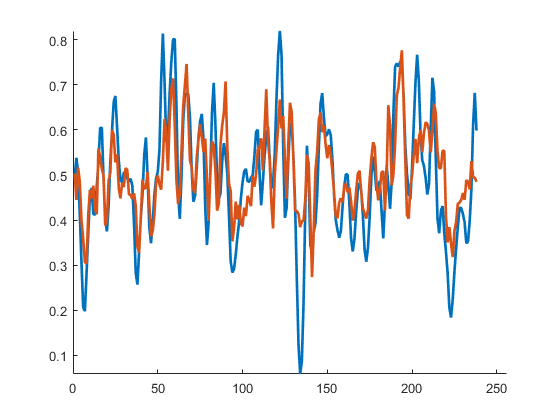


figure
hold on
plot(yt(2:end-2),'linewidth',2)
plot(ysim,'linewidth',2)
hold off
axis([0 256 -inf inf])


meanOSA = mean(VAF1)

meanOSA = 0.9339

meanMSA = mean(VAF)

meanMSA = 0.3987

% 
% 
% FY = mag2db(abs(fft(simfeaturez(3:end,1))));
% FZ = mag2db(abs(fft(yt)));
% 
% % heatmap(simfeaturez)
% % imagesc(simfeaturez)
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off